# JPEG: A COMMUNICATION SYSTEM 

## JACS

## Supplementary Materials

Copyright 2017-2018 Yiheng Wang Penicillin.

 王一恒 15307130257

 2017/12 - 2018/01

# JPEG ENCODING

## Procedure Preview:

oriimage (uint8) —— image (uint8) —— imageYUV (double) 

—— imageDCT (double) —— imageQ (double) —— messege

disp('----------------------')
disp('Thanks for using JACS.')
disp('----------------------')
disp('We are now doing source coding.')
disp('----------------------')
tic

## Step Zero: Read the Image

image_File_Name = 'Lena.tif';
oriimage = imread(image_File_Name);
Size = size(oriimage);
height = Size(1);    % height variable is used for later algorithm
width = Size(2);     % height variable is used for later algorithm
oriheight = height;    % Store the original height for image recovery
oriwidth = width;      % Store the original weight for image recovery

## Step One: Sampling

% The image may not be exactly divided into 8*8 blocks,
% so we need to extend its edges in such situation.
if mod(height,8) || mod(width,8)
    % If the image cannot br divided perfectly
    extendh = mod(8-mod(height,8),8);
    extendw = mod(8-mod(width,8),8);
    image = zeros(height+extendh,width+extendw,3);
    % Extend the right and bottom edge of the original image
    % The extended pixels are set to be black
    image(1:height,1:width,:) = oriimage;
    image = double(image);
    % Use image for later algorithm, and convert it to double
    Size = size(image);
    height = Size(1);
    width = Size(2);
    NY = height/8;    % Record the block number in the y axis
    NX = width/8;     % Record the block number in the x axis
else
    % If the image can be divided perfectly
    image = double(oriimage);
    NY = height/8;
    NX = width/8;
end

## Step Two: Convert RGB to YUV

imageYUV = zeros(height,width,3);

% RGB to YUV

K_R = 0.299;
K_G = 0.587;
K_B = 0.114;

% Y = K_R.*R + K_G.*G + K_B.*B;
% U = 1/2.*(B-Y)./(1-K_B);
% V = 1/2.*(R-Y)./(1-K_R);

% Y = 0.299*R + 0.587*G + 0.114*B
% U(Cb) = -0.1687*R - 0.3313*G + 0.5*B
% V(Cr) = 0.5*R - 0.4187*G - 0.0813*B

R = image(:,:,1) - 128;
G = image(:,:,2) - 128;
B = image(:,:,3) - 128;

Y = K_R.*R + K_G.*G + K_B.*B;
U = 1/2.*(B-Y)./(1-K_B);
V = 1/2.*(R-Y)./(1-K_R);

imageYUV(:,:,:) = cat(3,Y,U,V);

## Step Three: DCT

The principle of DCT is briefly summerized bellow:

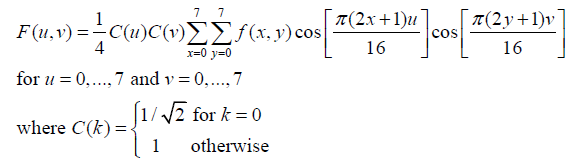

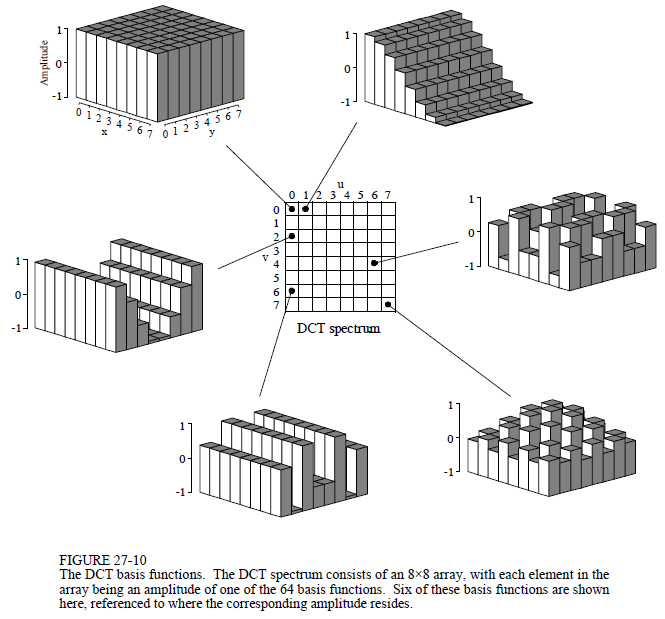

FDCT: F = $C^T*f*C$

C = $\sqrt{\frac{2}{N}}*\left(
\begin{array}{ccc}
\sqrt{1/2} & \sqrt{1/2} & ... & \sqrt{1/2}\\
cos(\frac{1}{2N}\pi) & cos(\frac{3}{2N}\pi) & ... & cos(\frac{2N-1}{2N}\pi)\\
... & ... & ... & ...\\
cos(\frac{N-1}{2N}\pi) & cos(\frac{3*(N-1)}{2N}\pi) & ... & cos(\frac{(2N-1)*(N-1)}{2N}\pi)\\
\end{array}
\right)$

IDCT: f = $C*f*C^T$

N = 8;    % Block size
temp = (0:N-1)'*(1:2:2*N-1).*pi./(2*N);
temp(1,:) = pi/4.*ones(1,N);
C = sqrt(2/N).*cos(temp);
% Create the base matrix for DCT

imageDCT = zeros(height,width,3);

% We accomplish this task here in a block-by-block fashion.
for yindex = 1:NY
    for xindex = 1:NX
        DCT_Y = C'*imageYUV(8*(yindex-1)+1:8*(yindex-1)+ ...
            8,8*(xindex-1)+1:8*(xindex-1)+8,1)*C;
        DCT_U = C'*imageYUV(8*(yindex-1)+1:8*(yindex-1)+ ...
            8,8*(xindex-1)+1:8*(xindex-1)+8,2)*C;
        DCT_V = C'*imageYUV(8*(yindex-1)+1:8*(yindex-1)+ ...
            8,8*(xindex-1)+1:8*(xindex-1)+8,3)*C;
        imageDCT(8*(yindex-1)+1:8*(yindex-1)+8,8*(xindex-1)+ ...
            1:8*(xindex-1)+8,:) = cat(3,DCT_Y,DCT_U,DCT_V);
    end
end

## Step Four: Quantization

The principle of quantization and the recommended quantization tables are shown bellow:

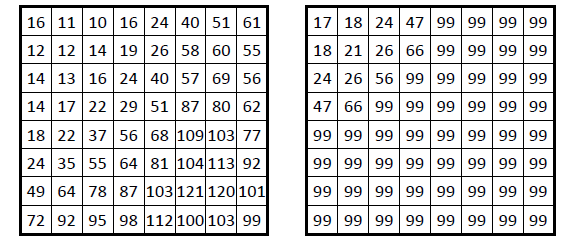

Y Quantization Table:

YQTable = [16 11 10 16 24 40 51 61; ...
    12 12 14 19 26 58 60 55; ...
    14 13 16 24 40 57 69 56; ...
    14 13 16 24 40 57 69 56; ...
    18 22 37 56 68 109 103 77; ...
    24 35 55 64 81 104 113 92; ...
    49 64 78 87 103 121 120 101; ...
    72 92 95 98 112 100 103 99];

UV Quantization Table:

UVQTable = [17 18 24 47 99 99 99 99; ...
    18 21 26 66 99 99 99 99; ...
    24 26 56 99 99 99 99 99; ...
    47 66 99 99 99 99 99 99; ...
    99 99 99 99 99 99 99 99; ...
    99 99 99 99 99 99 99 99; ...
    99 99 99 99 99 99 99 99; ...
    99 99 99 99 99 99 99 99];

Quantization:

% Create a full-size quatization table
YQT = ones(height,width);
UVQT = ones(height,width);
for yindex = 1:NY
    for xindex = 1:NX
        YQT(8*(yindex-1)+1:8*(yindex-1)+8, ...
            8*(xindex-1)+1:8*(xindex-1)+8) = YQTable;
        UVQT(8*(yindex-1)+1:8*(yindex-1)+8, ...
            8*(xindex-1)+1:8*(xindex-1)+8) = UVQTable;
    end
end

quality_factor = 1;
% Change the quality
% The bigger the quality_factor is, the higher the quatlity will be.
% The default quatization table roughly corresponds to 50% quality.
YQT = YQT./quality_factor;
UVQT = UVQT./quality_factor;

imageQ = cat(3,round(imageDCT(:,:,1)./YQT), ...
    round(imageDCT(:,:,2)./UVQT),round(imageDCT(:,:,3)./UVQT));

## Step Five: Z Scanning

Diagram:

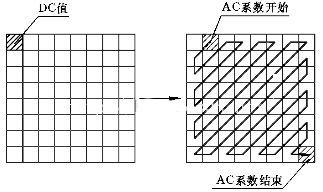

## 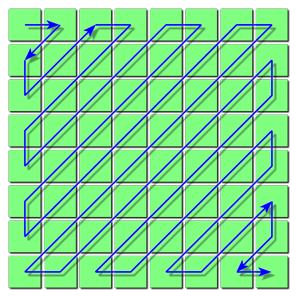

Zig_Zag = [1  2  6  7  15 16 28 29; ...
    3  5  8  14 17 27 30 43; ...
    4  9  13 18 26 31 42 44; ...
    10 12 19 25 32 41 45 54; ...
    11 20 24 33 40 46 53 55; ...
    21 23 34 39 47 52 56 61; ...
    22 35 38 48 51 57 60 62; ...
    36 37 49 50 58 59 63 64]; ...
    % Call function 'Zscan()'
% This function converts a two dimentional image
% into a matrix of size (NY*NX,64),
% with each row representing a 8*8 block
% and the first column representing the DC components.
Scan = cat(3,Zscan(imageQ(:,:,1),NY,NX,Zig_Zag), ...
    Zscan(imageQ(:,:,2),NY,NX,Zig_Zag),Zscan(imageQ(:,:,3),NY,NX,Zig_Zag));
% Divide the results into DC components and AC components
DC = Scan(:,1,:);        % This is a (NY*NX,1,3) matrix
DC = DC(:,1:3);          % Convert it into a (NY*NX,3) matrix
AC = Scan(:,2:64,:);     % This is a (NY*NX,63,3) matrix

# Encoding Example

Here we demonstrate how a quatized image is encoded for communication.

The DC coefficients and the AC coefficients are encoded differently.

## Step Six: *DPCM Coding* for DC Coefficients

**    Delta = DC_K (0,0) - DC_(K-1) (0,0)**

    Represented by **(Size, Value)**

**    Size**: Bit size of DC Delta value        ---    **Huffman Coding**

**    Value**: DC Delta value                      ---    **VLI Coding**

**For example:**

    D_(K-1) (0,0) = 12

    D_K (0,0) = 15

    Thus the code for D_K is (2,3)

## Step Seven: *RLE Coding* for AC Coefficients

    Run Length Encodiing: Representd by **(Run/Size, Value)**

**    Run**: Number of continuous 0        ---    **Huffman Coding**

**    Size**: Bit size of non-zero value        ---    **Huffman Coding **   

    **Value**: The next non-zeron value        ---    **VLI Codind**

**For example:**

**    35 7 0 0 0 -6 -2 0 0 -9 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 8 0 0 ... 0**

    the code is 

    **(0, 35) (0, 7) (3, -6) (0, -2) (2, -9) (15, 0) (2, 8) EOB**

    if size exceeds 16, then every 16 '0' is grouped and represented by (15, 0);

    if all the left values are '0', then it is represented by 'EOB'

## Step Eight: *VLI Coding* for 'Values'

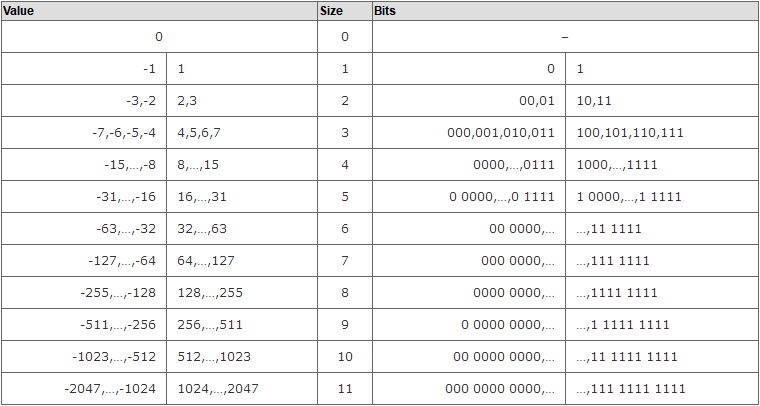

(0, 35)               (0, 7)           (3, -6)          (0, -2)        (2, -9)           (15, 0)    (2, 8)             EOB

(0, 6, 100011)   (0, 3, 111)   (3, 3, 001)   (0, 2, 01)    (2, 4, 0110)  (15, -)    (2, 4, 1000)   EOB(0, 0)

The first two numbers lie in the range 0~15, thus can be comined into a single byte,

with the fisrt four digits representing **Run** and the last four digits representing **Value **

(0x6,100011)    (0x3,111)    (0x33,001)    (0x2,01)    (0x24,0110)    (0xF0,-)    (0x24,1000)    EOB(0, 0)

## Step Nine: Huffman *Coding* for 'Size' or 'Run/Size'

Huffman table for DC and AC are different, for Y and UV are different as well,

so we need in total 4 Huffman tables

**For example:**

    For DC values, there is no '0' ahead, and 'Size' lies in the range 0~11

    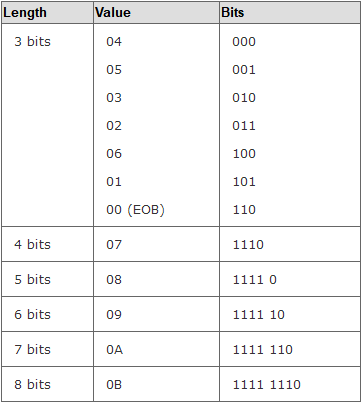

    0x6, for example, corresponds to code 100

    For AC values, 'Run' lies in the range 0~15, and 'Size' lies in the range 0~10

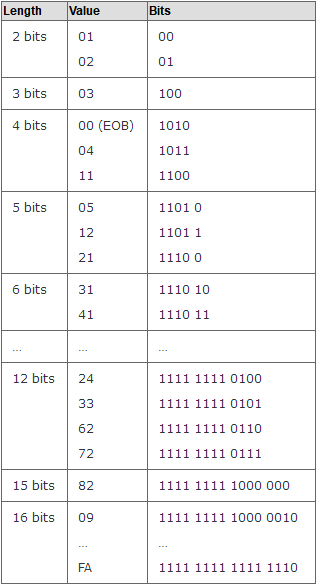

    0x33, for example, corresponds to code 1111 1111 0101

## Finally we will get:

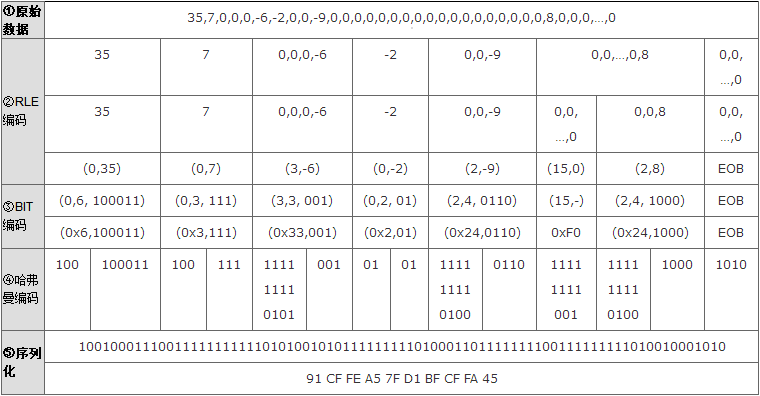

# Encode

We saw above how the quantized image can be encoded into a stream of 0 or 1 for communication.

Here we start to encode our own image.

% At first, we need to convert the quantized image into
% a intermediary representation before it can be encoded.


% DPCM Coding for the DC coefficients

% Calculate the differentces between DC coefficients
for i = NY*NX:-1:2;
    DC(i,:) = DC(i,:) - DC(i-1,:);
end

% Create a matrix to store the intermediary representations for 'Size'
DC_interS = zeros(NY*NX,3);

% Create a cell to store 'Value' codes
DC_V = cell(NY*NX,3);
% Create a cell to store 'Size' codes
DC_S = cell(NY*NX,3);


% RLE Coding for the AC coefficients

% Extract the nonzeros 'Value' from the AC coefficients
ACV = AC(:);
ACV(ACV == 0) = [];

% Create two matrix variable to store the
% intermediary representations for AC components
AC_interS = zeros(NY*NX,63,3);
% One for 'Size'
AC_interR = zeros(NY*NX,63,3);
% One for 'Run'

% Create a cell to store AC codes
AC_Code = cell(NY*NX,63,3);
AC_Code(:) = {' '};
% Create a cell to store 'Run/Size' codes
AC_RS = cell(NY*NX,63,3);

% As shown above, table for VLI coding and table for
% Huffman coding are needed to code the image.
% However, to incorporate such tables in our program here
% will be extremely cubersome.
% Hence, we shall generate our own Huffman table
% and 'VLI table' for each input image.
% And they will all be based on the Huffman coding scheme.

% First we generate the 'VLI table'.
% Note that we can generate a table for each YUV components,
% and thus achieve a higher compression rate.
% However, the more table we use, the more space
% it will take to run the program.
% The messege we send through the channal will grow as well.
% Hence, we will follow the example shown above
% and use one 'VLI table' for all the 'Value'.
% The Huffman table, though, will be tailored
% for Y_DC, UC_DC, Y_AC, UV_DC respectively.

## Huffman Table for Value

% First get the probabilities of all the 'Value' in both DC and AC components

Sta = tabulate([DC(:);ACV]);
% Call function 'huffman_scan()'
% This function takes a list of signals and their corresponding probabilities
% as input, and output the Huffman codes for these signals.
[Signal_Value,Code_Value] = huffman_code(Sta(:,1)',Sta(:,3)');
Signal_Value = cell2mat(Signal_Value);

## DC Intermediary Representation for Size

% Now we can tell the 'Size' according to the Code_Value

% For DC components
for i = 1:length(Signal_Value)
    templogic = DC==Signal_Value(i);
    DC_V(templogic) = Code_Value(i);
    DC_interS(templogic) = length(Code_Value{i});
end
% Now the 'Size' and 'Value' information are stored in two matrix, respectively

## DC Huffman Table for Size

% Then we generate the two Huffman tables for DC 'Size'
Sta = tabulate(DC_interS(:,1));
[Signal_DCY,Code_DCY] = huffman_code(Sta(:,1)',Sta(:,3)');
Signal_DCY = cell2mat(Signal_DCY);
% One for Y components
Sta = tabulate([DC_interS(:,2);DC_interS(:,3)]);
[Signal_DCUV,Code_DCUV] = huffman_code(Sta(:,1)',Sta(:,3)');
Signal_DCUV = cell2mat(Signal_DCUV);
% One for UV components

## DC Huffman Code for Size

% Now we can convert DC_interS into code
% For Y components
for i = 1:length(Signal_DCY)
    templogic = DC_interS==Signal_DCY(i);
    templogic(:,2:3) = 0;
    DC_S(templogic) = Code_DCY(i);
end
% For UV components
for i = 1:length(Signal_DCUV)
    templogic = DC_interS==Signal_DCUV(i);
    templogic(:,1) = 0;
    DC_S(templogic) = Code_DCUV(i);
end

## AC Intermediary Representation for Run/Size

% For AC components
% It is not that easy, because the format is heterogeneous for each block.
% Here, we will scan the AC matrix
% from the 1st (NY*NX,3) two dimentional matrix to the 63th.
% Note that we can also scan the 63 coefficients of each block.
% For higher speed, we do it matrix by matrix,
% although this requires a more sophisticated algorithm.

% We first convert the 'Value' into code, expect the '0'
% The length of the code can be stored simutaneously

Signal_Value_X = Signal_Value; % Make a copy
Erase = Signal_Value_X==0;
Signal_Value_X(Erase)=[];      % Erase the 0
Code_Value_X = Code_Value;     % Make a copy
Code_Value_X(Erase) = [];      % Erase the code as well

for i = 1:length(Signal_Value_X)
    templogic = AC==Signal_Value_X(i);
    AC_Code(templogic) = Code_Value_X(i);
    AC_interS(templogic) = length(Code_Value_X{i});
end

% Now we encode the Run length of 0

Count = zeros(NY*NX,3); % A count matrix to store the run lenght

% Check if EOB
Check = sum(AC(:,1:63,:)~=0,2);
Check = Check(:,1:3);
% Encode the EOB into AC_Code
tempCode = AC_Code(:,1,:);
tempCode(Check==0) = {'EOB'};
% This 'EOB' is simply as mark,
% and will be replaced by its code word later.
AC_Code(:,1,:) = tempCode;
% Disable the counter at the corresponding positon
Count(Check==0) = -127; % Arbitrarily taken

for i = 1:63     % Scan the 63 (NY*NX,3) two dimentional matrix
    temp = AC(:,i,:);     % Take out the ith matrix
    temp = temp(:,1:3);   % Flatten the matrix into tow dimentional
    
    templogic = temp==0; % If the current 'Value' is 0
    Count(templogic) = Count(templogic)+1;
    % Count the number of encountered 0
    
    tempcount = AC_interR(:,i,:); % If the current 'Value' is not 0
    tempcount(~templogic) = Count(~templogic);
    tempcount(Count==16) = 15; % If the Run length of 0 exceeds 15
    AC_interR(:,i,:) = tempcount; % Store the number of encountered 0
    
    % Reset the number of encountered 0
    Count(~templogic) = 0;
    Count(Count==16) = 0;
    
    % Check if EOB
    if i<63
        Check = sum(AC(:,i+1:63,:)~=0,2);
        Check = Check(:,1:3);
        % Encode the EOB into AC_V
        tempCode = AC_Code(:,i+1,:);
        tempCode(Check==0 & Count>=0) = {'EOB'};
        AC_Code(:,i+1,:) = tempCode;
        % Disable the counter at the corresponding positon
        Count(Check==0) = -127; % Arbitrarily taken
    end    
end

## AC Huffman Table for Run/Size

% What we have now is an intermediary AC_interS,
% which is a matrix containing the 'Size' in double format,
% and an intermediary AC_interR,
% which is a matrix containing the 'Run' in double format.
% AC_Code is already a cell containing the codes for 'Value'.

% The three matrix/cell have the same dimension,
% and for each nonempty element in AC_Code,
% the corresponding element in AC_interS stores the Size for it,
% and the corresponding element in AC_interR stroes the Run.

% However, some exception must be noticed.
% First, some elements in AC_Code are EOB.
% They have no corresponding elements in AC_interS or AC_interR.
% Second, some elements in AC_interR are 15.
% If the corresponding elements in AC_interS are 0,
% this will mean (15,0), which is 16 consecutive 0.
% There will be no corresponding elements in AC_Code.
% If the corresponding elements in AC_interS are not 0,
% this will mean (15,Value), with the code for 'Value' in
% the corresponding position in AC_Code.

% With these information in mind,
% we start to generate the Huffman Table for Run/Size.

% Combine Run and Size
AC_interRS = AC_interR.*100 + AC_interS;

ACY = AC_interRS(:,:,1);
ACY(ACY==0)=[];
Sta = tabulate([ACY(:);ones(NY*NX,1).*-1]);
% Note that we include the 'EOB' here, represented by -1.
% The number of EOB is roughly NY*NX*3 (one for each block)
[Signal_ACY,Code_ACY] = huffman_code(Sta(:,1)',Sta(:,3)');
Signal_ACY = cell2mat(Signal_ACY);
% One for Y components

ACUV = AC_interRS(:,:,2:3);
ACUV(ACUV==0)=[];
Sta = tabulate([ACUV(:);-1;ones(NY*NX*2,1).*-1]);
% Note that we include the 'EOB' here, represented by 0.
% The number of EOB is roughly NY*NX*2 (one for each block)
[Signal_ACUV,Code_ACUV] = huffman_code(Sta(:,1)',Sta(:,3)');
Signal_ACUV = cell2mat(Signal_ACUV);
% One for UV components

## AC Huffman Code for Run/Size

logic = zeros(NY*NX,63,3);
% Now we can convert AC_interRS into code
for i = 1:length(Signal_ACY)
    % For Y components
    templogic = AC_interRS==Signal_ACY(i);
    templogic(:,:,2:3) = 0;
    logic = logic+templogic;
    AC_RS(templogic) = Code_ACY(i);
end
for i = 1:length(Signal_ACUV)
    % For UV components
    templogic = AC_interRS==Signal_ACUV(i);
    templogic(:,:,1) = 0;
    logic = logic+templogic;
    AC_RS(templogic) = Code_ACUV(i);
end
logic = logical(logic);

## Send the Messege

% Now we have intotal four cell containing all the codes we need.
% DC_S and DC_V for DC components
% AC_RS and AC_V for AC components
% We encode them together block by block.
% Both of them contains three layers for Y,U,V
% We encode them separately.

DC_Code = strcat(DC_S,DC_V);

AC_Code(logic) = strcat(AC_RS(logic),AC_Code(logic));
% Combine the code for Size/Run and Value

DC_CodeX = cell(NY*NX,1,3);
DC_CodeX(:,1:3) = DC_Code;
% Two dimension to Three dimention

Code = [DC_CodeX,AC_Code];
% Combine the code for DC and AC

messegeY = cell2mat(reshape(Code(:,:,1)',1,NY*NX*64));
messegeU = cell2mat(reshape(Code(:,:,2)',1,NY*NX*64));
messegeV = cell2mat(reshape(Code(:,:,3)',1,NY*NX*64));
% Convert cell into string

messegeY(messegeY==' ')=[];
messegeU(messegeU==' ')=[];
messegeV(messegeV==' ')=[];
% Erase the blank elements

messegeY = strrep(messegeY,'EOB',Code_ACY{Signal_ACY==-1});
messegeU = strrep(messegeU,'EOB',Code_ACUV{Signal_ACUV==-1});
messegeV = strrep(messegeV,'EOB',Code_ACUV{Signal_ACUV==-1});
% Replace the 'EOB' into its code word

lengthY = length(messegeY);
lengthU = length(messegeU);
lengthV = length(messegeV);
Length = lengthY + lengthU + lengthV;


messege = strcat(messegeY,messegeU,messegeV);
Messege = messege;

TIME = toc;
disp('Source coding complete.')
disp(strcat('Times usage: ', num2str(TIME)))
disp('----------------------')
disp('we are now doing channel simulation.')
disp('----------------------')
tic

# JPEG CHANNEL

**Method One: HFC with Hamming Code**

(7,4) Hamming Code.

% G = [1 0 0 0 1 0 1; ...
%     0 1 0 0 1 1 1; ...
%     0 0 1 0 1 1 0; ...
%     0 0 0 1 0 1 1];
% H = [1 1 1 0 1 0 0; ...
%     0 1 1 1 0 1 0; ...
%     1 1 0 1 0 0 1];
% % First we split the messege into 4-bits pieces
% append = mod(4 - mod(length(messege),4),4);
% messege = strcat(messege,num2str(zeros(1,append)));
% messege = str2num(messege(:))';
% % Add 0 at the end of the messege
% % Now the lenght of the messege is 4*N
%
% currentL = length(messege);
% Num = currentL/4;
% Rec = zeros(1,currentL);
%
% % Initiate the noise
% Perror = 0.01; % Set the error rate
% Noise = rand(1,7*Num);
% Noise(Noise<Perror) = 1;
% Noise(Noise~=1) = 0;
%
% for i = 1:Num % Send the messege piece by piece
%     % Noise
%     currentrec = bitxor(mult2ple(messege(4*(i-1)+1:4*i),G),Noise(7*(i-1)+1:7*i));
%     % Error Correction
%     switch num2str(mult2ple(currentrec,H'))
%         case '0  0  0'
%             Rec(4*(i-1)+1:4*i) = currentrec(1:4);
%         case '1  0  1'
%             temp = bitxor(currentrec,[1 0 0 0 0 0 0]);
%             Rec(4*(i-1)+1:4*i) = temp(1:4);
%         case '1  1  1'
%             temp = bitxor(currentrec,[0 1 0 0 0 0 0]);
%             Rec(4*(i-1)+1:4*i) = temp(1:4);
%         case '1  1  0'
%             temp = bitxor(currentrec,[0 0 1 0 0 0 0]);
%             Rec(4*(i-1)+1:4*i) = temp(1:4);
%         case '0  1  1'
%             temp = bitxor(currentrec,[0 0 0 1 0 0 0]);
%             Rec(4*(i-1)+1:4*i) = temp(1:4);
%         case '1  0  0'
%             temp = bitxor(currentrec,[0 0 0 0 1 0 0]);
%             Rec(4*(i-1)+1:4*i) = temp(1:4);
%         case '0  1  0'
%             temp = bitxor(currentrec,[0 0 0 0 0 1 0]);
%             Rec(4*(i-1)+1:4*i) = temp(1:4);
%         case '0  0  1'
%             temp = bitxor(currentrec,[0 0 0 0 0 0 1]);
%             Rec(4*(i-1)+1:4*i) = temp(1:4);
%     end
% end

As shown above, the naive way to do error correction in Hamming code is to use 'switch-case'.

But it will require tremendous amount of work to built a system for large n and k (and is slow).

Here we provide a autonomous 'Hamming code generator' to generate any possible Hamming code.

% n = 7;
% k = 4;
% % Only need to change these two lines
%
% append = mod(k - mod(length(messege),k),k);
% messege = strcat(messege,num2str(zeros(1,append)));
% messege = str2num(messege(:))';
%
% H = HGenerate(n-k);
% H = [H;H(2:n-k+1,:)];
% H(1:n-k+1,:) = [];
% H = H';
% G = H(:,1:k);
% G = [eye(k),G'];
%
% currentL = length(messege);
% Num = currentL/k;
% Rec = zeros(1,currentL);
%
% % Initiate the noise
% Perror = 0.01;
% Noise = rand(1,n*Num);
% Noise(Noise<Perror) = 1;
% Noise(Noise~=1) = 0;
%
% for i = 1:Num % Send the messege piece by piece
%     % Noise
%     currentrec = bitxor(mult2ple(messege(k*(i-1)+1:k*i),G),Noise(n*(i-1)+1:n*i));
%     % Error Correction
%     tempS = mult2ple(currentrec,H');
%     tempS = tempS';
%     if sum(tempS) == 0
%         Rec(k*(i-1)+1:k*i) = currentrec(1:k);
%     else
%         position = 1;
%         while sum(tempS == H(:,position)) ~= n-k
%             position = position+1;
%         end
%         error = zeros(1,n);
%         error(position)=1;
%         correction = bitxor(currentrec,error);
%         Rec(k*(i-1)+1:k*i) = correction(1:k);
%     end
% end

## Method Two: ARQ with CRC

(38, 22) CRC, with g(x) = x^16 + x^12 + x^5 + 1  [1 0 0 0 1 0 0 0 0 0 0 1 0 0 0 0 1]

% append = mod(22 - mod(length(messege),22),22);
% messege = strcat(messege,num2str(zeros(1,append)));
% messege = str2num(messege(:))';
%
% gx =  [1 0 0 0 1 0 0 0 0 0 0 1 0 0 0 0 1];
% currentL = length(messege);
% Num = currentL/22;
% Rec = zeros(1,currentL);
%
% Trytimes = zeors(1,Num);
% % This is used to record how much times it takes
% % to succesfully send a piece of messege of length 22.
%
% for i = 1:Num
%     currentmessege = [messege(11*(i-1)+1:11*i) zeros(1,16)];
%     temp = currentmessege;
%
%     while(1) % Compute r(x)
%         if sum(temp)>0
%             pivot = find(temp == 1);
%         else
%             break
%         end
%         if (length(temp)-pivot(1))<16
%             break
%         end
%         temp(pivot(1):pivot(1)+16) = bitxor(temp(pivot(1):pivot(1)+16),gx);
%     end
%     currentsend = [currentmessege temp(length(temp)-15:length(temp))];
%     % r(x) always contains 16 words
%
%     Trytimes(i) = 1;
%     while(1)
%         % Add noise
%         Perror = 0.01; % The probability of error can be variable as well
%         Noise = rand(1,38);
%         Noise(Noise<Perror) = 1;
%         Noise(Noise~=1) = 0;
%         currentrec = bitxor(currentsend,Noise);
%
%         % Check if there is an error
%         temp = currentrec;
%         while(1) % Compute r(x)
%             if sum(temp)>0
%                 pivot = find(temp == 1);
%             else
%                 break
%             end
%             if (length(temp)-pivot(1))<16
%                 break
%             end
%             temp(pivot(1):pivot(1)+16) = bitxor(temp(pivot(1):pivot(1)+16),gx);
%         end
%
%         if sum(temp)==0   % Success
%             break
%         else
%             Trytimes(i) = Trytimes(i) + 1; % Send the messege again
%         end
%     end
% end

## Method Three: FEC with Concolutional Code

(3,1,2) convolutional code, with transfer function matrix [1, 1+D, 1+D+D^2]

% %% Convolutional Encoding
% 
% k = 1;
% n = 3;
% L = 2;
% %%%%%%
% %%% To change the code, these lines should be modified.
% %%%%%%
% 
% append = mod(k - mod(length(messege),k),k);
% messege = strcat(messege,num2str(zeros(1,append)));
% messege = str2num(messege(:))';
% 
% % Specify the transfer matrix
% G = zeros(k,n,L+1);
% G(:,:,1) = [1,1,1]; % G0
% G(:,:,2) = [0,1,1]; % G1
% G(:,:,3) = [0,0,1]; % G2
% %%%%%%
% %%% To change the code, these lines should be modified.
% %%%%%%
% 
% 
% currentL = length(messege);
% Num = currentL/k;
% Send = zeros(Num+L,n);
% realmessege = messege;
% messege = [realmessege, zeros(1,k*L)];
% 
% % Initiate the noise
% Perror = 0.01;
% Noise = rand(Num+L,n);
% Noise(Noise<Perror) = 1;
% Noise(Noise~=1) = 0;
% 
% 
% Stack = zeros(L+1,k); % Create a stack to store the current information
% 
% 
% for i=1:Num+L
%     
%     % Information Flow
%     for j = L+1:-1:2
%         Stack(j,:) = Stack(j-1,:); % Move the information flow
%     end
%     Stack(1,:)= messege(k*(i-1)+1:k*i); % New information
%     
%     % Code Genaration
%     for j = 1:L+1
%         Send(i,:) = bitxor(Send(i,:),mult2ple(Stack(j,:),G(:,:,j)));
%         Send(i,:) = bitxor(Send(i,:),Noise(i,:));
%     end
%     
% end
% 
% 
% %% Convolutional Decoding: Viterbi algorithm
% 
% D = 9; % Time Delay. Must be non-negative. Can be arbitrarily modified.
% Recbox = zeros(1,n*(Num+D+L));
% 
% % Create a memory cell
% State = 4; % Four states for (3,1,2) code
% %%%%%%
% %%% To change the code, this lines should be modified.
% %%% Because different code have different number of states.
% %%%%%%
% 
% Memo = cell(State,D);
% for i = 1:State
%     for j = 1:D
%         Memo{i,j} = zeros(1,n); % Initiate the memory cell
%     end
% end
% 
% % Create a PM vector
% PM = ones(State,1)*Inf;
% PM(1) = 0;
% 
% 
% % Create a referrence cell for the calculation of BM
% % and for the updating of the memory cell
% Ref = cell(State,State);
% Ref{1,1}=[0 0 0];Ref{1,3}=[1 1 1];
% Ref{2,1}=[0 0 1];Ref{2,3}=[1 1 0];
% Ref{3,2}=[0 1 1];Ref{3,4}=[1 0 0];
% Ref{4,2}=[0 1 0];Ref{4,4}=[1 0 1];
% %%%%%%
% %%% To change the code, these lines should be modified.
% %%%%%%
% 
% % Create a BM matrix
% BM = zeros(4,4);
% bm = zeros(4,4);
% bm(1,2)=Inf;bm(1,4)=Inf;
% bm(2,2)=Inf;bm(2,4)=Inf;
% bm(3,1)=Inf;bm(3,3)=Inf;
% bm(4,1)=Inf;bm(4,3)=Inf;
% %%%%%%
% %%% To change the code, this lines should be modified.
% %%%%%%
% 
% % Decoding start
% 
% for count = 1:Num+L
%     currentcode = Send(count,:);
%     
%     % Calculate BM
%     for i = 1:State
%         for j = 1:State
%             if ~isempty(Ref{i,j})
%                 BM(i,j)=sum(bitxor(Ref{i,j},currentcode));
%             end
%         end
%     end
%     
%     % Update PM and the memory cell
%     currentmin = Inf;
%     newPM = zeros(State,1);
%     tempBM = BM + bm;
%     newMemo = cell(State,D);
%     
%     for i = 1:State
%         newPM(i) = min(PM+tempBM(:,i));
%         if newPM(i) ~= Inf
%             Index = find((PM+tempBM(:,i)) == newPM(i));
%             Index = Index(1);
%             newMemo(i,1:D-1) = Memo(Index,2:D);
%             newMemo(i,D) = Ref(Index,i);
%             if newPM(i)<currentmin
%                 currentmin = newPM(i);
%                 output = Memo{Index,1};
%             end
%         end
%     end
%     
%     PM = newPM;
%     Memo = newMemo;
%     Recbox(n*(count-1)+1:n*count) = output;
% end
% 
% % Extract the rest of the memory cell.
% Recbox(n*(Num+L)+1:n*(Num+L+D)) = cell2mat(Memo(Index,1:D));
% Recbox = reshape(Recbox,3,Num+L+D)';
% 
% % From code to messege
% 
% % Create a referece matrix. The decoder refer to this matrix,
% % and find the corresponding k-bit messege of the current n-bit code
% mRef = zeros(2,2,2);
% %%%%%%
% %%% To change the code, these lines should be modified.
% %%% This matrix is specifically designed for our code here.
% %%%%%%
% mRef(2,2,2)=1;
% mRef(2,2,1)=1;
% mRef(2,1,1)=1;
% mRef(2,1,2)=1;
% 
% Rec=zeros(1,currentL+L+D);
% for i = 1:Num+L+D
%     currentcode = Recbox(i,:);
%     Rec(i) = mRef(currentcode(1)+1,currentcode(2)+1,currentcode(3)+1);
% end
% 
% % The real messege is
% Rec = Rec(D+1:D+currentL);

TIME = toc;
disp('Channel simulation complete.')
disp(strcat('Times usage: ', num2str(TIME)))
disp('----------------------')
disp('We are now doing source decoding.')
disp('This may take a while, please wait patiently.')
disp('----------------------')
tic

# JPEG DECODING

## Procedure Preview:

recmessege —— decoded —— revimageZ(double) —— 

revimageQ (double) —— IDCT(double) —— revimage (uint8) 

Rec = Messege;
Rec = num2str(Rec);
Rec(Rec==' ') = '';
recmessegeY = Rec(1:lengthY);
recmessegeU = Rec(lengthY+1:lengthY+lengthU);
recmessegeV = Rec(lengthY+lengthU+1:Length);

% Decode the messege into pixel values

% For Y components
decodedY = zeros(1,NY*NX*64);
currentelement = 1; % Start with the first pixel
BlockCount = NY*NX;
prev = 0;
while BlockCount > 0
    Stop = 1;
    tempcode = recmessegeY(1:Stop); % The current code
    % The first element of a block is a DC coefficient.
    % Thus we shall refer to the DC Huffman Table,
    % which is stored as Signal_DCY and Code_DCY
    indexDC = find(strcmp(Code_DCY,tempcode));
    while isempty(indexDC) % If the current code is not a code word
        Stop = Stop + 1; % Eat the next code bit
        tempcode = recmessegeY(1:Stop);
        indexDC = find(strcmp(Code_DCY,tempcode));
    end % Until the current code is a code word for DC 'Size'
    Size = Signal_DCY(indexDC);
    % Successfully decode the DC 'Size'
    % The next Size bits will be the code word for DC 'Value'
    indexDC = find(strcmp(Code_Value,recmessegeY(Stop+1:Stop+Size)));
    decodedY(currentelement) = Signal_Value(indexDC) + prev;
    prev = decodedY(currentelement);
    % Reverse DPCM Coding
    recmessegeY(1:Stop+Size) = []; % Erase the decoded messege
    currentelement = currentelement + 1;
    % Move on to AC coefficients
    %a=input('Move on to AC')
    ACCount = 63;
    while ACCount > 0
        Stop = 1;
        tempcode = recmessegeY(1:Stop); % The current code
        indexAC = find(strcmp(Code_ACY,tempcode));
        while isempty(indexAC) % If the current code is not a code word
            Stop = Stop + 1; % Eat the next code bit
            tempcode = recmessegeY(1:Stop);
            indexAC = find(strcmp(Code_ACY,tempcode));
        end % Until the current code is a code word for AC 'Run/Size'
        RunSize = Signal_ACY(indexAC);
        % Successfully decode the AC 'Run/Size'
        % Check if EOB first
        if RunSize == -1
            decodedY(currentelement:currentelement+ACCount-1) = 0;
            recmessegeY(1:Stop) = []; % Erase the decoded messege
            currentelement = currentelement + ACCount;
            ACCount = 0;
        else
            Run = floor(RunSize/100); % Decode the 'Run' information
            if Run > 0
                decodedY(currentelement:currentelement+Run-1) = 0;
                currentelement = currentelement + Run;
                ACCount = ACCount - Run;
            end
            Size = mod(RunSize,100); % Decode the 'Size' information
            if Size == 0 % This happens only for 16 consecutive 0
                decodedY(currentelement) = 0;
                recmessegeY(1:Stop) = []; % Erase the decoded messege
                currentelement = currentelement +1;
            else % The next Size bits will be the code word for AC 'Value'
                index = find(strcmp(Code_Value,recmessegeY(Stop+1:Stop+Size)));
                decodedY(currentelement) = Signal_Value(index);
                recmessegeY(1:Stop+Size) = []; % Erase the decoded messege
                currentelement = currentelement + 1;
            end
            ACCount = ACCount - 1; % Move on to the next AC coefficient
        end
    end
    BlockCount = BlockCount - 1; % Move on to the next Block
end

disp('***')
disp('Source Decoding: 60%')
disp('***')

% For U components
decodedU = zeros(1,NY*NX*64);
currentelement = 1; % Start with the first pixel
BlockCount = NY*NX;
prev = 0;
while BlockCount > 0
    Stop = 1;
    tempcode = recmessegeU(1:Stop); % The current code
    % The first element of a block is a DC coefficient.
    % Thus we shall refer to the DC Huffman Table,
    % which is stored as Signal_DCY and Code_DCY
    indexDC = find(strcmp(Code_DCUV,tempcode));
    while isempty(indexDC) % If the current code is not a code word
        Stop = Stop + 1; % Eat the next code bit
        tempcode = recmessegeU(1:Stop);
        indexDC = find(strcmp(Code_DCUV,tempcode));
    end % Until the current code is a code word for DC 'Size'
    Size = Signal_DCUV(indexDC);
    % Successfully decode the DC 'Size'
    % The next Size bits will be the code word for DC 'Value'
    indexDC = find(strcmp(Code_Value,recmessegeU(Stop+1:Stop+Size)));
    decodedU(currentelement) = Signal_Value(indexDC) + prev;
    prev = decodedU(currentelement);
    % Reverse DPCM Coding
    recmessegeU(1:Stop+Size) = []; % Erase the decoded messege
    currentelement = currentelement + 1;
    % Move on to AC coefficients
    %a=input('Move on to AC')
    ACCount = 63;
    while ACCount > 0
        Stop = 1;
        tempcode = recmessegeU(1:Stop); % The current code
        indexAC = find(strcmp(Code_ACUV,tempcode));
        while isempty(indexAC) % If the current code is not a code word
            Stop = Stop + 1; % Eat the next code bit
            tempcode = recmessegeU(1:Stop);
            indexAC = find(strcmp(Code_ACUV,tempcode));
        end % Until the current code is a code word for AC 'Run/Size'
        RunSize = Signal_ACUV(indexAC);
        % Successfully decode the AC 'Run/Size'
        % Check if EOB first
        if RunSize == -1
            decodedU(currentelement:currentelement+ACCount-1) = 0;
            recmessegeU(1:Stop) = []; % Erase the decoded messege
            currentelement = currentelement + ACCount;
            ACCount = 0;
        else
            Run = floor(RunSize/100); % Decode the 'Run' information
            if Run > 0
                decodedU(currentelement:currentelement+Run-1) = 0;
                currentelement = currentelement + Run;
                ACCount = ACCount - Run;
            end
            Size = mod(RunSize,100); % Decode the 'Size' information
            if Size == 0 % This happens only for 16 consecutive 0
                decodedU(currentelement) = 0;
                recmessegeU(1:Stop) = []; % Erase the decoded messege
                currentelement = currentelement +1;
            else % The next Size bits will be the code word for AC 'Value'
                index = find(strcmp(Code_Value,recmessegeU(Stop+1:Stop+Size)));
                decodedU(currentelement) = Signal_Value(index);
                recmessegeU(1:Stop+Size) = []; % Erase the decoded messege
                currentelement = currentelement + 1;
            end
            ACCount = ACCount - 1; % Move on to the next AC coefficient
        end
    end
    BlockCount = BlockCount - 1; % Move on to the next Block
end

disp('***')
disp('Source Decoding: 80%')
disp('***')

% For V components
decodedV = zeros(1,NY*NX*64);
currentelement = 1; % Start with the first pixel
BlockCount = NY*NX;
prev = 0;
while BlockCount > 0
    Stop = 1;
    tempcode = recmessegeV(1:Stop); % The current code
    % The first element of a block is a DC coefficient.
    % Thus we shall refer to the DC Huffman Table,
    % which is stored as Signal_DCY and Code_DCY
    indexDC = find(strcmp(Code_DCUV,tempcode));
    while isempty(indexDC) % If the current code is not a code word
        Stop = Stop + 1; % Eat the next code bit
        tempcode = recmessegeV(1:Stop);
        indexDC = find(strcmp(Code_DCUV,tempcode));
    end % Until the current code is a code word for DC 'Size'
    Size = Signal_DCUV(indexDC);
    % Successfully decode the DC 'Size'
    % The next Size bits will be the code word for DC 'Value'
    indexDC = find(strcmp(Code_Value,recmessegeV(Stop+1:Stop+Size)));
    decodedV(currentelement) = Signal_Value(indexDC) + prev;
    prev = decodedV(currentelement);
    % Reverse DPCM Coding
    recmessegeV(1:Stop+Size) = []; % Erase the decoded messege
    currentelement = currentelement + 1;
    % Move on to AC coefficients
    %a=input('Move on to AC')
    ACCount = 63;
    while ACCount > 0
        Stop = 1;
        tempcode = recmessegeV(1:Stop); % The current code
        indexAC = find(strcmp(Code_ACUV,tempcode));
        while isempty(indexAC) % If the current code is not a code word
            Stop = Stop + 1; % Eat the next code bit
            tempcode = recmessegeV(1:Stop);
            indexAC = find(strcmp(Code_ACUV,tempcode));
        end % Until the current code is a code word for AC 'Run/Size'
        RunSize = Signal_ACUV(indexAC);
        % Successfully decode the AC 'Run/Size'
        % Check if EOB first
        if RunSize == -1
            decodedV(currentelement:currentelement+ACCount-1) = 0;
            recmessegeV(1:Stop) = []; % Erase the decoded messege
            currentelement = currentelement + ACCount;
            ACCount = 0;
        else
            Run = floor(RunSize/100); % Decode the 'Run' information
            if Run > 0
                decodedV(currentelement:currentelement+Run-1) = 0;
                currentelement = currentelement + Run;
                ACCount = ACCount - Run;
            end
            Size = mod(RunSize,100); % Decode the 'Size' information
            if Size == 0 % This happens only for 16 consecutive 0
                decodedV(currentelement) = 0;
                recmessegeV(1:Stop) = []; % Erase the decoded messege
                currentelement = currentelement +1;
            else % The next Size bits will be the code word for AC 'Value'
                index = find(strcmp(Code_Value,recmessegeV(Stop+1:Stop+Size)));
                decodedV(currentelement) = Signal_Value(index);
                recmessegeV(1:Stop+Size) = []; % Erase the decoded messege
                currentelement = currentelement + 1;
            end
            ACCount = ACCount - 1; % Move on to the next AC coefficient
        end
    end
    BlockCount = BlockCount - 1; % Move on to the next Block
end

disp('***')
disp('Source Decoding: 99%')
disp('***')

% Reverse Z Scanning
revimageZY = revZscan(decodedY,NY,NX,Zig_Zag);
revimageZU = revZscan(decodedU,NY,NX,Zig_Zag);
revimageZV = revZscan(decodedV,NY,NX,Zig_Zag);

% Reverse quantization
revimageQY = revimageZY.*YQT;
revimageQU = revimageZU.*UVQT;
revimageQV = revimageZV.*UVQT;

% Reverse DCT
IDCT_Y = zeros(height,width);
IDCT_U = IDCT_Y;
IDCT_V = IDCT_Y;


for yindex = 1:NY
    for xindex = 1:NX
        IDCT_Y(8*(yindex-1)+1:8*(yindex-1)+8,8*(xindex-1)+1:8*(xindex-1)+8) ...
            = C*revimageQY(8*(yindex-1)+1:8*(yindex-1)+8,...
            8*(xindex-1)+1:8*(xindex-1)+8,1)*C';
        IDCT_U(8*(yindex-1)+1:8*(yindex-1)+8,8*(xindex-1)+1:8*(xindex-1)+8) ...
            = C*revimageQU(8*(yindex-1)+1:8*(yindex-1)+8,...
            8*(xindex-1)+1:8*(xindex-1)+8,1)*C';
        IDCT_V(8*(yindex-1)+1:8*(yindex-1)+8,8*(xindex-1)+1:8*(xindex-1)+8) ...
            = C*revimageQV(8*(yindex-1)+1:8*(yindex-1)+8,...
            8*(xindex-1)+1:8*(xindex-1)+8,1)*C';
    end
end

% YUV to RGB

%  R = Y + 1.402*V
%  G = Y - 0.34414*U - 0.71414*V
%  B = Y + 1.772*U

R = IDCT_Y + 1.402.*IDCT_V + 128;
G = IDCT_Y - 0.34414.*IDCT_U - 0.71414.*IDCT_V + 128;
B = IDCT_Y + 1.772.*IDCT_U + 128;

revimage = uint8(cat(3,R,G,B));

% Reframe if necessary
revimage = revimage(1:oriheight,1:oriwidth,:);

TIME = toc;
disp('Source decoding complete.')
disp(strcat('Times usage: ', num2str(TIME)))
disp('----------------------')
disp('Now press enter to see the reconstructed image.')
pause
imshow(revimage)
disp('Thanks for using JACS. Bye.')